# Dynamic Models with Latent Variables: Final Project

## Timothée Dangleterre and Giovanni Manche

Work based on the paper: A new approach to model regime switching, Chang et al. 2017, *Journal of Econometrics* 

clear; clc;
addpath('utils');

### 1. Simulations

rng(100);
% Volatility model for now
params_true = create_params(0.8, 0.0, -0.5, [0; 0], [], [0.04; 0.12], 0);
y = simulate_data(500, params_true);
% mettre load data qd on aura données réelles

### 2. Initial values

%% Valeurs initiales
theta = [0.5; 0; 0; mean(y)-std(y); mean(y)+std(y); 0.8*std(y); 1.2*std(y)];

%% Bornes
lb = [-1; -Inf; -1; -Inf; -Inf; 1e-6; 1e-6];
ub = [ 1;  Inf;  1;  Inf;  Inf;  Inf;  Inf];

%% Optimisation
options = optimoptions('fmincon', 'Display', 'iter', 'MaxFunEvals', 3000);
f = @(x) LL_regime_switching(x, y, 1, 2);

[x, fval, exitflag] = fmincon(f, theta, [], [], [], [], lb, ub, [], options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       8    1.000000e+10    0.000e+00    0.000e+00

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<


%% Résultats
disp(table(x(1), x(2), x(3), x(4), x(5), x(6), x(7), ...
    'VariableNames', ["alpha", "tau", "rho", "mu_low", "mu_high", "sigma_low", "sigma_high"]));

    alpha    tau    rho     mu_low      mu_high     sigma_low    sigma_high
    _____    ___    ___    _________    ________    _________    __________

     0.5      0      0     -0.094665    0.092599    0.074906      0.11236  



### 2. GDP

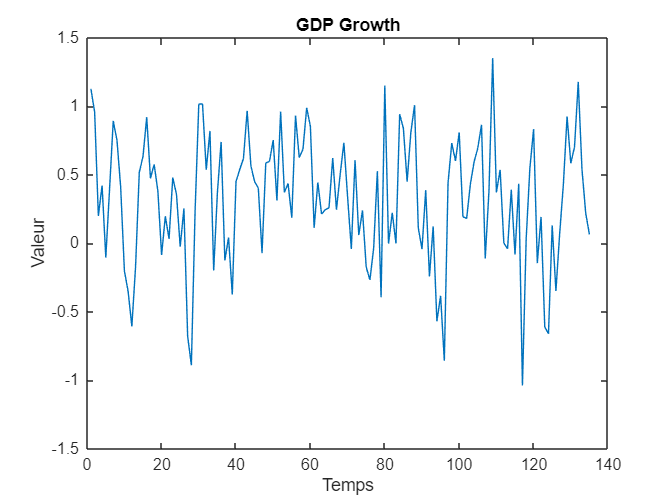

dataGDP = readmatrix("Hamilton.xlsx",'Sheet', 'GNP82', "NumHeaderLines", 1);
y = dataGDP(:, 2);
figure;
plot(y); title("GDP Growth"); xlabel("Temps"); ylabel("Valeur");

%% Parameters
k = 4;
r = 2;

%% AR(4)
if exist('arima', 'file')
    mdl = arima(4, 0, 0);
    mdl_fit = estimate(mdl, y, 'Display', 'off');
    gamma_init = cell2mat(mdl_fit.AR)';
else
    Y_lag = y(5:end);
    X_lag = [y(4:end-1), y(3:end-2), y(2:end-3), y(1:end-4)];
    gamma_init = X_lag \ Y_lag;
end

%% Recessions (growth < 0 ou < threshold)
recession_idx = (y < 0);
expansion_idx = ~recession_idx;

mu_low_init = mean(y(recession_idx));
mu_high_init = mean(y(expansion_idx));
sigma_init = std(y);

fprintf('=== EMPIRICAL MEANS ===\n');

=== EMPIRICAL MEANS ===


fprintf('Recession (y<0):  mu = %.3f%%, n = %d\n', mu_low_init, sum(recession_idx));

Recession (y<0):  mu = -0.301%, n = 33


fprintf('Expansion (y>=0): mu = %.3f%%, n = %d\n', mu_high_init, sum(expansion_idx));

Expansion (y>=0): mu = 0.525%, n = 102


fprintf('Overall:          sigma = %.3f%%\n\n', sigma_init);

Overall:          sigma = 0.465%




%% Initial value (10 parameters)
theta = [
    0.8;            % alpha
    0;              % tau
    0;              % rho
    mu_low_init;    % mu_low 
    mu_high_init;   % mu_high 
    gamma_init;     % gamma(1:4)
    sigma_init      % sigma (only one here (mean model)
];

%% Bounds: alpha, tau, rho, mu_low, mu_high, gamma(1:k), sigma_low, sigma_high
lb = [-0.99; -Inf; -1.0; -Inf; -Inf; -Inf(k,1); 1e-6];
ub = [ 1.0;  Inf;  1.0;  Inf;  Inf;  Inf(k,1);  Inf];

%% Test filter
fprintf('=== TESTING FILTER ===\n');

=== TESTING FILTER ===


theta_test = [theta(1:5); theta(6:9); theta(10); theta(10)];  % Same sigma for both models
params_test = vector_to_params(theta_test, k, r);

try
    [log_L_test, ~, ~] = ms_threshold_filter(y, params_test);
    fprintf('Filter OK: Log-L = %.4f\n\n', log_L_test);
catch ME
    fprintf('Filter FAILED: %s\n', ME.message);
    error('Fix initial values');
end

Filter OK: Log-L = -89.9837




%% Optimisation
fprintf('=== OPTIMIZATION (MEAN MODEL) ===\n');

=== OPTIMIZATION (MEAN MODEL) ===


options = optimoptions('fmincon', ...
    'Display', 'iter', ...
    'MaxFunctionEvaluations', 500, ...
    'MaxIterations', 200);

f = @(x) LL_regime_switching(x, y, k, r, 'mean');

tic;
[x, fval, exitflag] = fmincon(f, theta, [], [], [], [], lb, ub, [], options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      11    8.998366e+01    0.000e+00    2.829e+01


    1      28    8.227469e+01    0.000e+00    6.363e+01    2.892e-01


    2      42    8.003846e+01    0.000e+00    9.552e+01    1.889e-01
    3      57    7.975299e+01    0.000e+00    9.934e+00    2.830e-01


    4      71    7.958621e+01    0.000e+00    2.216e+01    9.517e-02
    5      86    7.654872e+01    0.000e+00    8.672e+00    1.376e-01


    6     106    7.623056e+01    0.000e+00    6.819e+00    3.062e-02


    7     118    7.593617e+01    0.000e+00    1.203e+01    7.308e-02
    8     131    7.560771e+01    0.000e+00    3.373e+01    8.732e-01
    9     145    7.549804e+01    0.000e+00    3.762e+01    4.327e-01
   10     159    7.545848e+01    0.000e+00    1.613e+01    1.645e-01
   11     176    7.531988e+01    0.000e+00    2.807e+00    1.112e-01
   12     188    7.516176e+01    0.000e+00    9.419e+00    2.131e-01
   13     202    7.504634e+01    0.000e+00    9.564e+00    3.869e-01
   14     215    7.478798e+01    0.000e+00    1.466e+01    9.313e-02
   15     229    7.450159e+01    0.000e+00    1.435e+01    1.709e-01
   16     240    7.425106e+01    0.000e+00    6.379e+00    2.546e-01
   17     253    7.406282e+01    0.000e+00    3.577e+00    8.760e-02
   18     264    7.396760e+01    0.000e+00    5.236e+00    1.801e-01
   19     275    7.386144e+01    0.000e+00    1.335e+00    5.049e-02
   20     286    7.384564e+01    0.000e+00    1.812e+00    5.857e-02
   21     297    7.383077e+01    0

time_elapsed = toc;

%% Results
fprintf('\n=== RESULTS (MEAN MODEL) ===\n');


=== RESULTS (MEAN MODEL) ===


fprintf('Exit flag: %d\n', exitflag);

Exit flag: 0


fprintf('Time: %.1f seconds\n', time_elapsed);

Time: 1247.9 seconds


fprintf('Log-L: %.4f\n\n', -fval);

Log-L: -73.8216




disp(table(x(1), x(2), x(3), x(4), x(5), x(6), x(7), x(8), x(9), x(10), ...
    'VariableNames', ["alpha", "tau", "rho", "mu_low", "mu_high", ...
                      "gamma1", "gamma2", "gamma3", "gamma4", "sigma"]));

     alpha       tau         rho        mu_low      mu_high    gamma1      gamma2      gamma3      gamma4      sigma 
    _______    ________    ________    _________    _______    _______    ________    ________    ________    _______

    0.93308    -0.89232    -0.77175    -0.038376    0.52817    0.11845    0.044755    -0.25989    -0.15867    0.34886




fprintf('\nMean difference: %.3f%% (expansion - recession)\n', x(5) - x(4));


Mean difference: 0.567% (expansion - recession)


fprintf('Volatility: %.3f%% (constant across regimes)\n', x(10));

Volatility: 0.349% (constant across regimes)
